%
clear
clc
close all


disp('')
disp('Многомерная оптимизация методом Гаусса - Зайделя (покоординатный спуск)')

Многомерная оптимизация методом Гаусса - Зайделя (покоординатный спуск)


disp('')
disp('Предварительно должна быть задана функция в файле fun3.m')

Предварительно должна быть задана функция в файле fun3.m


disp('Задайте пределы для построения графиков в файле. ')

Задайте пределы для построения графиков в файле. 






% Пределы для построения графиков
N = 30;
ax = -10;
bx = 10;
hx = (bx-ax)/N;
ay = -10;
by = 10;
hy = (by-ay)/N;
disp(['Пределы по оси X: ', num2str([ax,bx])])

Пределы по оси X: -10  10


disp(['Пределы по оси Y: ', num2str([ay,by])])

Пределы по оси Y: -10  10




 global global_p global_edir
isConstStep = 0;
method = menu('Задайте метод оптимизации','С постоянным шагом','скорейший спуск');
if method ==1,
 isConstStep = 1;
end





disp('Задайте количество шагов и величину постоянного шага в файле. ')

Задайте количество шагов и величину постоянного шага в файле. 


nmax = 10;
dd = 2;
disp(['Величина шага: ', num2str(dd)])

Величина шага: 2




eps = dd/2;
dtext = 0.2;

[X,Y] = meshgrid(ax:hx:bx,ay:hy:by);
Z = fun3(X,Y);
figure(1)
contour(X,Y,Z,30)
[U,V] = gradient(Z,0.2,0.2);
hold on


disp('Задайте начальную точку графически ')

Задайте начальную точку графически 


disp('Далее наблюдайте за процессом поиска на двумерном графике линий уровня функции ')

Далее наблюдайте за процессом поиска на двумерном графике линий уровня функции 


disp('и на трехмерном графике функции ')

и на трехмерном графике функции 


disp('Фоновое изображение (линии уровня, градиент, трехмерная картина) дано для понимания происходящего ')

Фоновое изображение (линии уровня, градиент, трехмерная картина) дано для понимания происходящего 


p0 = ginput(1);
p = p0;
fp = fun3(p(1),p(2));
fp0=fp;


plot(p0(1),p0(2),'ks')
text(p0(1)+dtext ,p0(2)+dtext,'START')
quiver(X,Y,U,V)


disp(['Начальная точка: ', num2str(p0)])

Начальная точка: 6.0405     -6.0047


%p0 = [ax+(bx-ax)*rand(1); ay+(by-ay)*rand(1)];
disp('    n     x     y     f(x,y)')

    n     x     y     f(x,y)


disp([0, p0, fp0])   

         0    6.0405   -6.0047  112.7142



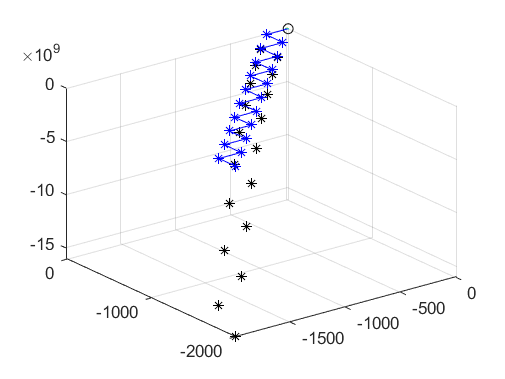

   1.0e+07 *

    0.0000   -0.0000   -0.0000   -1.6159

   1.0e+08 *

    0.0000   -0.0000   -0.0000   -1.2855

   1.0e+08 *

    0.0000   -0.0000   -0.0000   -4.3317

   1.0e+09 *

    0.0000   -0.0000   -0.0000   -1.0260

   1.0e+09 *

    0.0000   -0.0000   -0.0000   -2.0031

   1.0e+09 *

    0.0000   -0.0000   -0.0000   -3.4604

   1.0e+09 *

    0.0000   -0.0000   -0.0000   -5.4940

   1.0e+09 *

    0.0000   -0.0000   -0.0000   -8.1998

   1.0e+10 *

    0.0000   -0.0000   -0.0000   -1.1674



   1.0e+10 *

    0.0000   -0.0000   -0.0000   -1.6012






figure(2)
mesh(X,Y,Z)
hold on
plot3(p0(1),p0(2),fun3(p0(1),p0(2)),'ko')
contour(X,Y,Z,30)


flag = 0;
for n=1:nmax
 pold = p;   
 for i=1:length(p),


  if isConstStep==1,
   max1dsteps = 1;
   h1d = dd;
  else
   max1dsteps = 1000;
   h1d = dd/10;
  end
  global_p = p;
  global_edir = zeros(size(global_p));
  global_edir(i)=1;


  [xopt,fp1]=opt1ddir('fun3p',0,h1d,max1dsteps);
  p1 = p+global_edir*xopt;
  fp2 = fun3(p1(1),p1(2));

  figure(1)
  plot(p1(1),p1(2),'bo')
  plot([p(1),p1(1)],[p(2),p1(2)],'b')

  figure(2)

  plot3(p1(1),p1(2),fp1,'k*')
  plot3(p1(1),p1(2),0,'b*')
  plot3([p(1),p1(1)],[p(2),p1(2)],[0,0],'b')
%  plot3([p(1),p1(1)],[p(2),p1(2)],[fun3(p(1),p(1)),fun3(p1(1),p1(1))],'k-')



  p = p1;
  fp=fp1;

 end

 disp([n, p, fp])   
 figure(1)
 plot(p(1),p(2),'ks')
 text(p(1)+dtext ,p(2)+dtext ,num2str(n))
 if norm(p-pold)<eps,
    break
 end   
end 

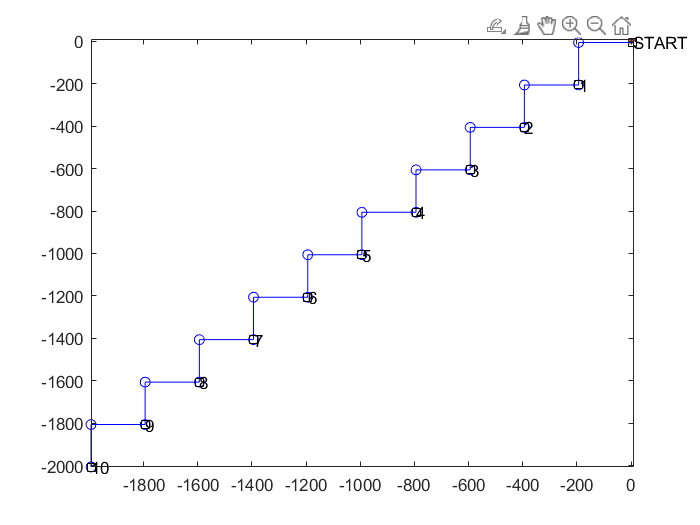

hold off




disp('Постройте график значения целевой функции от номера шага. ')

Постройте график значения целевой функции от номера шага. 
